# This is Question 2 of the assignment

%sys = tf([5,1.5,7],[7,1.5,5]);

z = [-2.5, 2];
p = [0, -7+2i, -7-2i];
k = 1;
G = zpk(z,p,k);

Now plotting the pole-zero diagram.

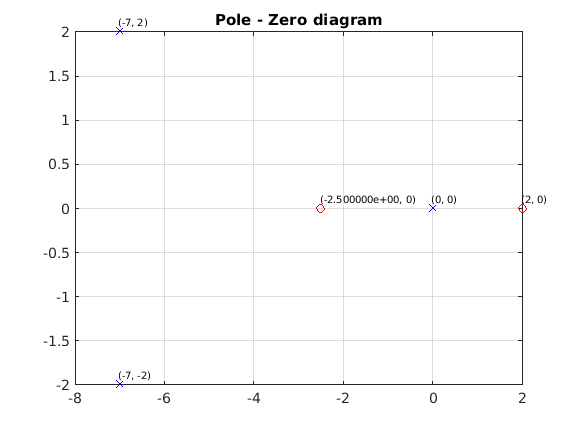

len_p = length(p);
len_z = length(z);

for i = 1:len_p
    plot(real(p(1,i)),imag(p(1,i)),'bX')
    textString1 = sprintf('(%d, %d)', real(p(1,i)), imag(p(1,i)));
    text(real(p(1,i))-0.03, imag(p(1,i))+0.1, textString1, 'FontSize', 7);
    hold on
end

for j = 1:len_z
    plot(real(z(1,j)),imag(z(1,j)),'rO')
    textString2 = sprintf('(%d, %d)', real(z(1,j)), imag(z(1,j)));
    text(real(z(1,j))-0.03, imag(z(1,j))+0.1, textString2, 'FontSize', 7);
    hold on
end

grid on
title('Pole - Zero diagram') 

Marking the co-ordinate axis for better view of stability.

x_abscissa = [-8 4]

x_abscissa =     -8     4


y_abscissa = [0 0]

y_abscissa =      0     0


plot(x_abscissa,y_abscissa,'color', 'black')
xlabel('Real Axis')

x_ord = [0 0]

x_ord =      0     0


y_ord = [-3 3]

y_ord =     -3     3


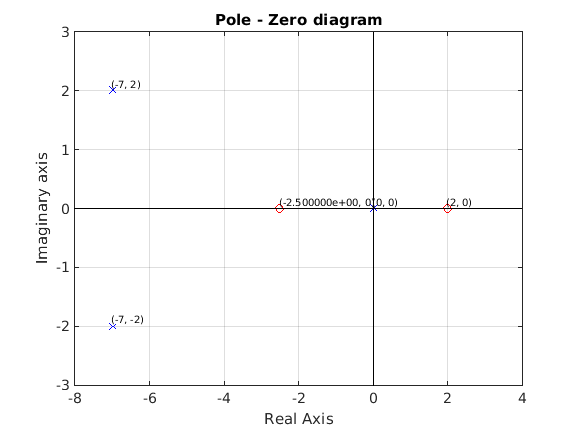

plot(x_ord,y_ord,'color', 'black')
ylabel('Imaginary axis')

Creating the circles now

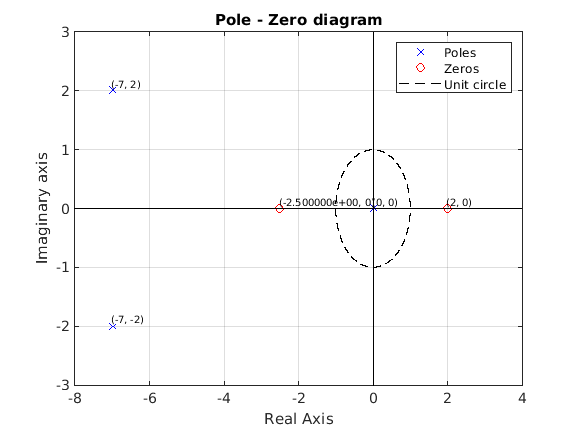

% for unit circle:
a = -pi:0.001:pi;
x_u_cir = cos(a);
y_u_cir = sin(a);

plot(x_u_cir,y_u_cir,'k--')
legend('Poles', '','','Zeros','','','','Unit circle');
hold off;